# Main para preprocesamiento de datos de nichos

clear; clc; close all;

### 2. Set the path to the folder containing the layer data

layerfolder = 'data/Capas_SouthAmerica_2.5M/'

layerfolder = 'data/Capas_SouthAmerica_2.5M/'

### 3. Read in the layer data from the specified folder using ReadLayers:

-  To execute ReadLayers, there is one required input and three optional inputs.

                Layers = ReadLayers(layer_folder, parallel, nanvalue)

Layers = ReadLayers(layerfolder);

----Reading layers----
Elapsed time is 38.698086 seconds.


## Niche generation

### 1. Generate initial point for niche generation using a virtual species method.

- To execute InitialPoint, there is one required input and six optional inputs.

- The default value for method is 'coeff'

 InitialPoint = InitialPoint(layers, method, plotting, random_point, point, coeff, deformations_limit)

InfoInitialPoint = InitialPoint(Layers,'harmonic', false);

### 2. Generate the niche map using niche generation algorithm with the initial point

Map = NicheGeneration(Layers, InitialPoint, occupation, plotting)

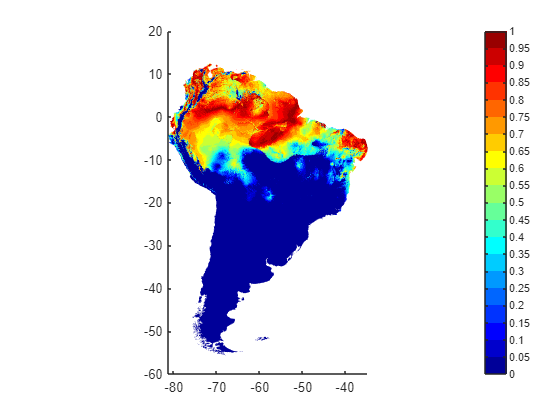

MapInfo = NicheGeneration(Layers, InfoInitialPoint, 0.5, true);

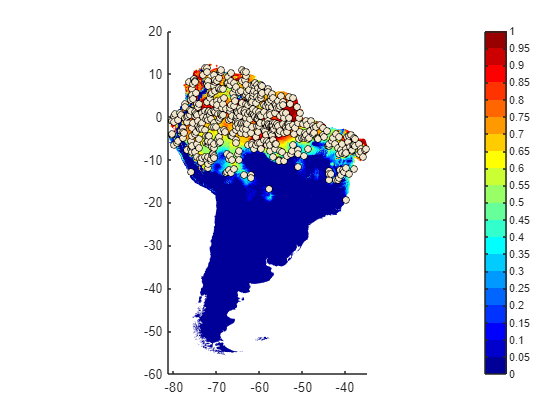

T = 499×22 table
    Name      LONG        LAT        bio1      bio2      bio3     bio4    bio5    bio6     bio7     bio8    bio9    bio10    bio11    bio12     bio13     bio14     bio15     bio16     bio17     bio18     bio19 
    _____    _______    ________    ______    ______    ______    ____    ____    ____    ______    ____    ____    _____    _____    ______   

T = samplingVS(Layers, InfoInitialPoint, MapInfo, 500, -1, true, 'GenSP', true, true)

## Creación del objeto nicho (preprocesamiento de los datos)

El objeto se crea a partir de la tabla de observaciones de la especie, un método de normalización y los índices de las columnas de la tabla con información relevante para la modelación. Hay 3 métodos disponibles

- 1: Normalización con el intervalo [0 1] y removiendo outliers multivariados

- 2: Normalización estándar

- 3: Normalización robusta

niche=nicheData(T,3,4:22)

niche =   nicheData with properties:

       nData: [100×19 double]
        nObs: 100
       nVars: 19
        inds: [4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22]
    varNames: {'bio1'  'bio2'  'bio3'  'bio4'  'bio5'  'bio6'  'bio7'  'bio8'  'bio9'  'bio10'  'bio11'  'bio12'  'bio13'  'bio14'  'bio15'  'bio16'  'bio17'  'bio18'  'bio19'}
    clusters: []
      agents: []
     RAgents: []
       Graph: []


### Encontrar cluster de variables correlacionadas

Los clusters se crean a partir de un threshold para la correlación. Se considera que 2 variables pertenecen al mismo cluster si su índice de correlación supera el threshold en valor absoluto.

thr = 0.8;
niche=niche.aClus(thr)

niche =   nicheData with properties:

       nData: [100×19 double]
        nObs: 100
       nVars: 19
        inds: [4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22]
    varNames: {'bio1'  'bio2'  'bio3'  'bio4'  'bio5'  'bio6'  'bio7'  'bio8'  'bio9'  'bio10'  'bio11'  'bio12'  'bio13'  'bio14'  'bio15'  'bio16'  'bio17'  'bio18'  'bio19'}
    clusters: [7×19 logical]
      agents: [1 2 3 7 12 14 18]
     RAgents: [7×1 logical]
       Graph: []


### Crear los predictores finales

Con base en los representantes de cluster y los errores de regresión para cada representante. Es necesario correr esta línea de código para posteriormente generar la función de preprocesamiento de los datos

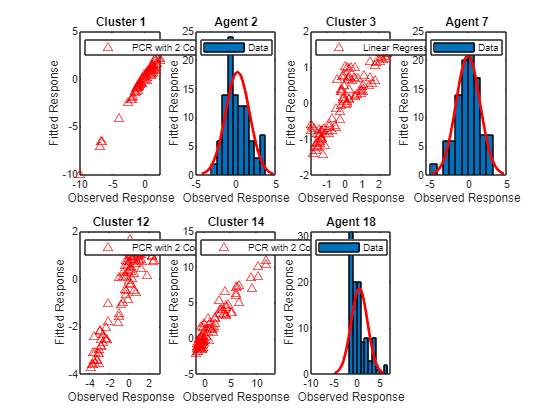

Cluster for Agent 1 is:
     1     5     6     8     9    10    11

Cluster for Agent 2 is:
     2

Cluster for Agent 3 is:
     3     4

Cluster for Agent 7 is:
     7

Cluster for Agent 12 is:
    12    13    16    19

Cluster for Agent 14 is:
    14    15    17

Cluster for Agent 18 is:
    18



niche=niche.regressor;

## Activación de la función de preprocesamiento

Se corre esta línea de código para activar la función de preprocesamiento. Dicha función tiene como dominio el conjunto de variables ambientales original y su rango son los representantes de cluster normalizados y sus respectivos errores normalizados. En general no tiene inversa.

niche=niche.setProcFun()

niche =   nicheData with properties:

       nData: [100×19 double]
        nObs: 100
       nVars: 19
        inds: [4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22]
    varNames: {'bio1'  'bio2'  'bio3'  'bio4'  'bio5'  'bio6'  'bio7'  'bio8'  'bio9'  'bio10'  'bio11'  'bio12'  'bio13'  'bio14'  'bio15'  'bio16'  'bio17'  'bio18'  'bio19'}
    clusters: [7×19 logical]
      agents: [1 2 3 7 12 14 18]
     RAgents: [7×1 logical]
       Graph: []


### Ejemplo de preprocesamiento de los datos

pData sería el input de los algoritmos de modelado de nicho

pData = niche.procFun(T{:,niche.inds})

pData =    -6.5720    1.5133    2.1358   -1.5000   -3.0642    1.1500   -0.4573   -0.0449    1.2302    0.6715   -1.1140
   -6.8524    1.6903    2.2742   -1.5000   -1.0615    9.2500    3.4085    1.0377    1.7687    1.1193    2.6412
    0.4317    0.2212    0.0721   -0.1667   -3.4221   -1.3500    0.2988    0.9286   -1.4832   -0.4702    0.5182
    1.0074   -0.5221    0.2773   -1.1667   -3.0342   -0.4500   -0.9451   -0.9326   -1.0743    0.1768    0.6651
    1.0443   -0.5044    0.4233   -1.3333   -3.1790   -0.1500   -0.7866   -0.6704   -0.8732    0.3418    1.2087
    0.2251    1.4956    1.0069   -0.1667   -2.8347    1.9500   -0.6890   -1.1802    0.9409    0.0360    0.3472
   -0.6679    0.8761    0.3020    0.1667   -2.2309    2.0500    0.3720   -1.0843    0.3589    0.4228   -0.9787
    1.3173    1.0000    0.1471    0.5000   -3.6079   -1.2500   -0.0915    1.1637   -1.3423   -0.7454    0.6685
    0.7786    1.5133    0.6363    0.3333   -2.4249    3.0500    0.4695   -1.1963    0.7886    0.1466   -

[bio,nanind2] = niche.map2vec(Layers.Z)

bio = 1.0e+03 *

    0.0257    0.0069    0.0884    0.0305    0.0298    0.0220    0.0078    0.0260    0.0255    0.0262    0.0255    2.3250    0.2990    0.0920    0.0398    0.8400    0.3100    0.7600    0.3350
    0.0258    0.0069    0.0896    0.0292    0.0298    0.0221    0.0077    0.0261    0.0255    0.0262    0.0255    2.3260    0.2980    0.0970    0.0395    0.8360    0.3270    0.7620    0.3270
    0.0258    0.0069    0.0886    0.0295    0.0299    0.0221    0.0078    0.0261    0.0256    0.0262    0.0256    2.3140    0.2920    0.0900    0.0406    0.8370    0.3000    0.7900    0.3000
    0.0257    0.0069    0.0892    0.0296    0.0297    0.0220    0.0077    0.0260    0.0255    0.0261    0.0255    2.3370    0.3010    0.0930    0.0387    0.8410    0.3200    0.7620    0.3450
    0.0258    0.0069    0.0893    0.0307    0.0298    0.0221    0.0077    0.0261    0.0255    0.0262    0.0255    2.3230    0.3000    0.0950    0.0397    0.8500    0.3360    0.7620    0.3390
    0.0258    0.0069    0.08

nanind2 = 2929848×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
